## Data Preparation

trainlabel = labels(1:170,:);

traindata = features(1:170,:);

testdata = features(171:210,:);

testlabel = labels(171:210,:);

% Converting the testlabel and labels to an array
% to compare with the predicted results

labels_array = table2array(labels);
testlabel_array = table2array(testlabel);

## Training

%model = fitcknn(traindata, trainlabel)

model = fitcknn(...
    traindata, ...
    trainlabel, ...
    'Distance', 'Euclidean', ...
    'Exponent', [], ...
    'NumNeighbors', 21, ...
    'DistanceWeight', 'Equal', ...
   'Standardize', true, ...
    'ClassNames', [1; 2; 3])

model =   ClassificationKNN
           PredictorNames: {'VAR1'  'VAR2'  'VAR3'  'VAR4'  'VAR5'  'VAR6'  'VAR7'}
             ResponseName: 'CLASS'
    CategoricalPredictors: []
               ClassNames: [1 2 3]
           ScoreTransform: 'none'
          NumObservations: 170
                 Distance: 'euclidean'
             NumNeighbors: 21


  Properties, Methods


## Testing the Data

predicted_testlabel = predict(model, testdata);

## Compare the Results

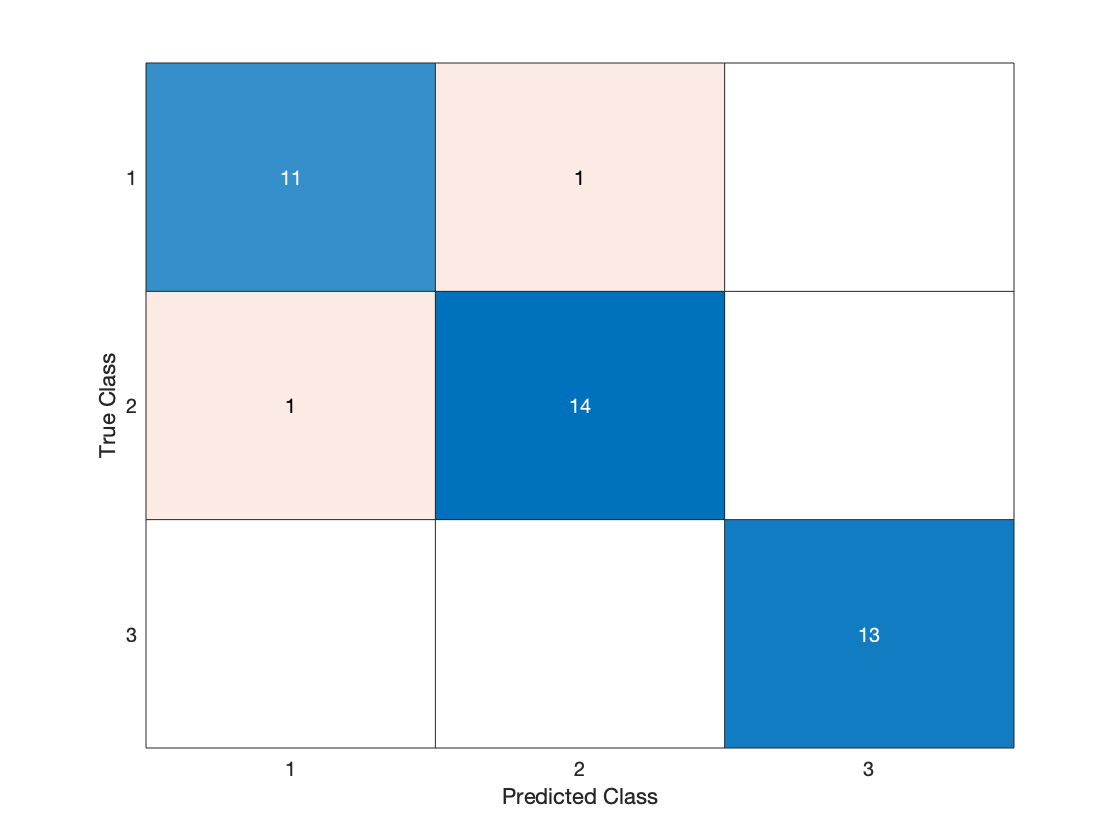


%confusion mat
ConfMat = confusionmat(testlabel_array, predicted_testlabel);
confusionchart(ConfMat);


%Calculate Accuary Rate
wrongPredictionsArr = testlabel_array == predicted_testlabel;

wrongPredictions = sum(wrongPredictionsArr(:) == 0)

wrongPredictions = 2


noe = numel(testlabel_array);

accuracyRate = ((noe-wrongPredictions)/noe)*100

accuracyRate = 95

## All Data

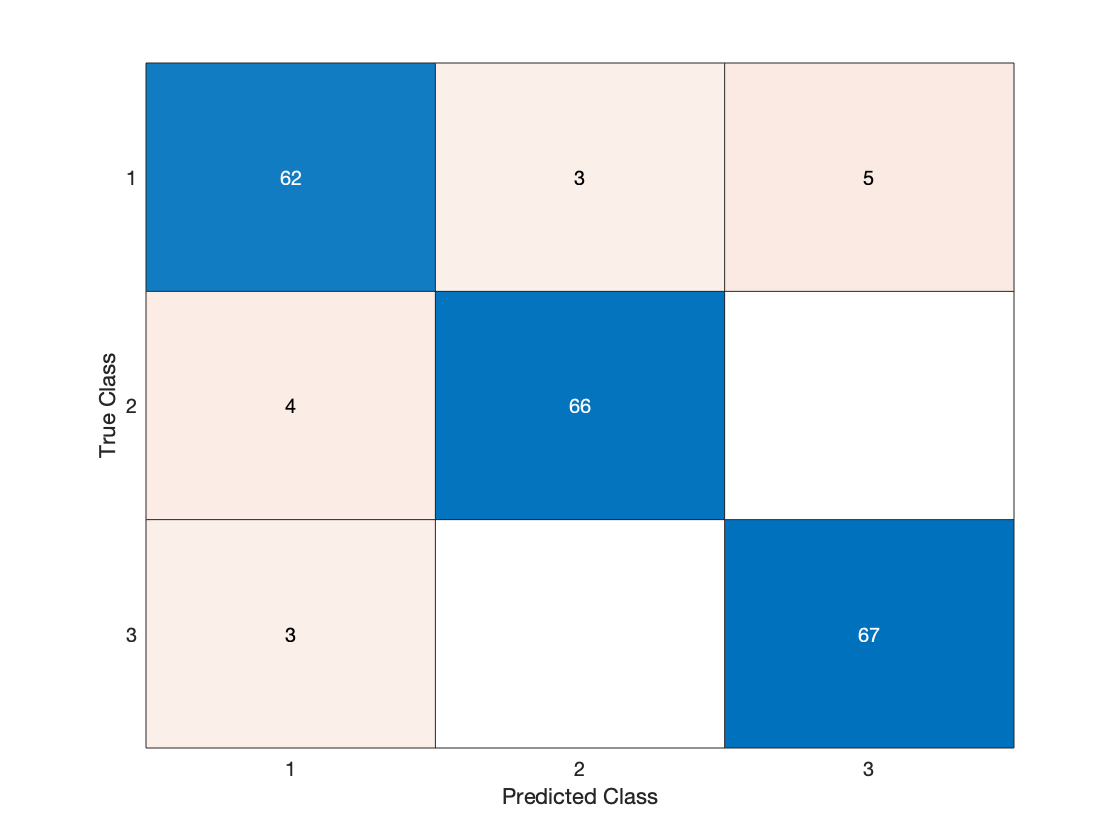

predicted_labels = predict(model, features);

%confusion mat

ConfMat = confusionmat(labels_array,predicted_labels);
confusionchart(ConfMat);


%Accuary Rate

wrongPredictionsArr = labels_array == predicted_labels;
wrongPredictions = sum(wrongPredictionsArr(:) == 0)

wrongPredictions = 15

noe = numel(labels_array);
accuracyRate2 = ((noe-wrongPredictions)/noe)*100

accuracyRate2 = 92.8571